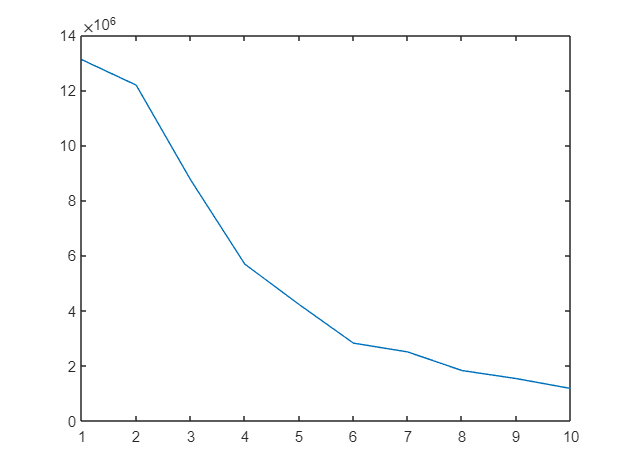

import data_fruit.*

%Storing the data of each image as a four dimensional matrix
images=zeros(80, 80, 3, 16);
images(:, :, :, 1)=image_1;
images(:, :, :, 2)=image_2;
images(:, :, :, 3)=image_3;
images(:, :, :, 4)=image_4;
images(:, :, :, 5)=image_5;
images(:, :, :, 6)=image_6;
images(:, :, :, 7)=image_7;
images(:, :, :, 8)=image_8;
images(:, :, :, 9)=image_9;
images(:, :, :, 10)=image_10;
images(:, :, :, 11)=image_11;
images(:, :, :, 12)=image_12;
images(:, :, :, 13)=image_13;
images(:, :, :, 14)=image_14;
images(:, :, :, 15)=image_15;
images(:, :, :, 16)=image_16;

%Resizing the matrix into a 19200 by 16 matrix
imageResize=reshape(images, [19200, 16]);
mean=zeros(19200, 1);
mean=double(mean);
mean=sum(imageResize,2)/16; %Calculating the mean
covMatrix=((imageResize-mean)*((imageResize-mean)'))/16; %Calculating the covariance matrix
[EigenVec, EigenVal]=eigs(covMatrix, 10);%Finding the 10 largest eigen values and vectors
EigenVal=diag(EigenVal);% Converting the diagonal matrix to a vector
plot(EigenVal);%Plotting the top ten eigen values

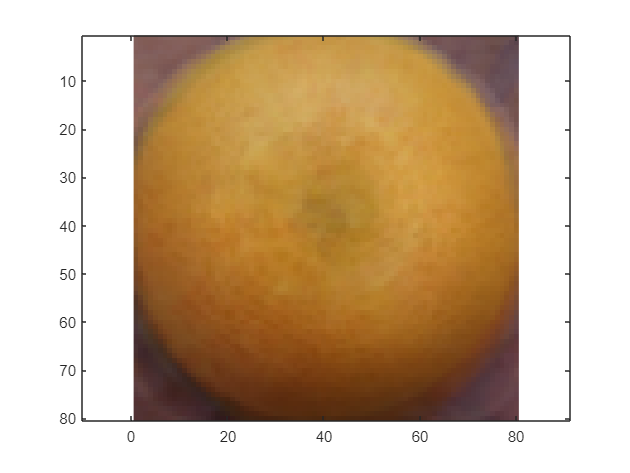


meanFruit=uint8(mean);
imagesc(reshape(meanFruit, [80, 80, 3]));%Displaying the mean as a fruit
axis equal;

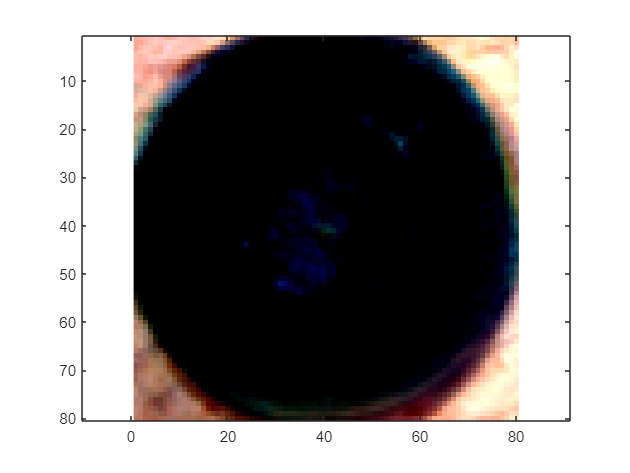

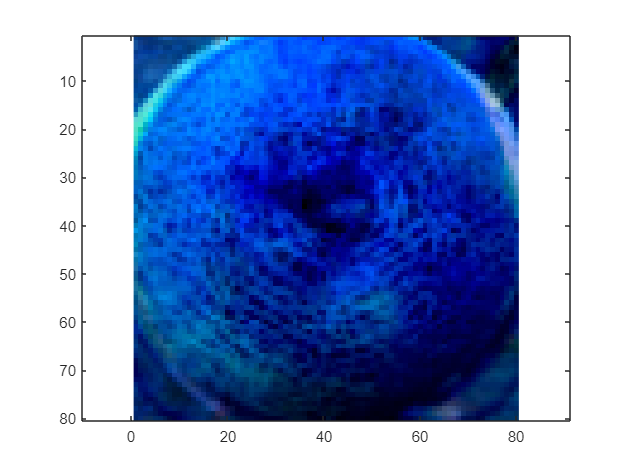

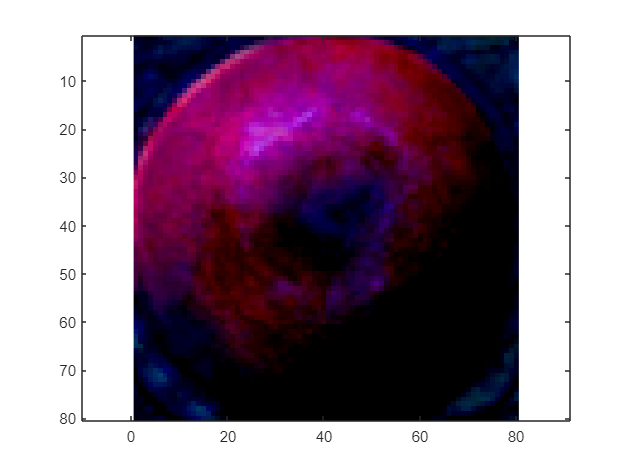

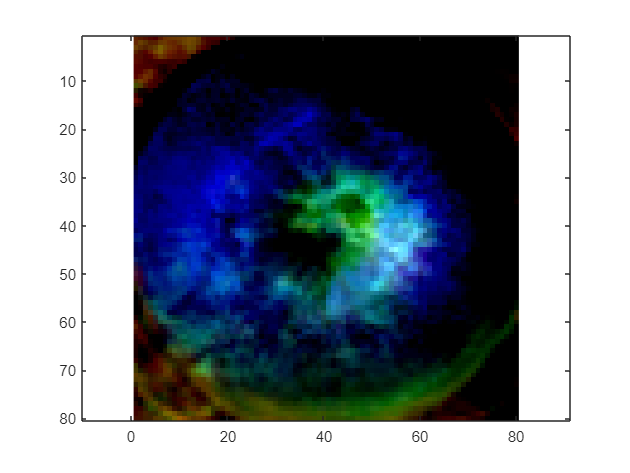


for z=1:4
    figure, imagesc(reshape(uint8((sqrt((mean')*(mean))).*EigenVec(:, z)), [80,80,3]));%Displaying the top four eigen vectors (scaled to the mean) as fruits
    axis equal;
end

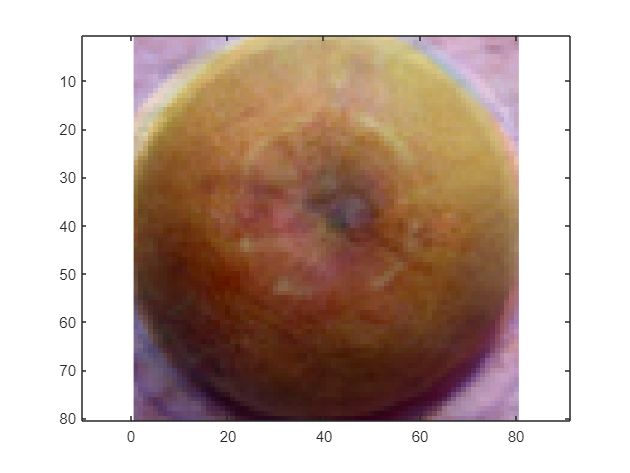

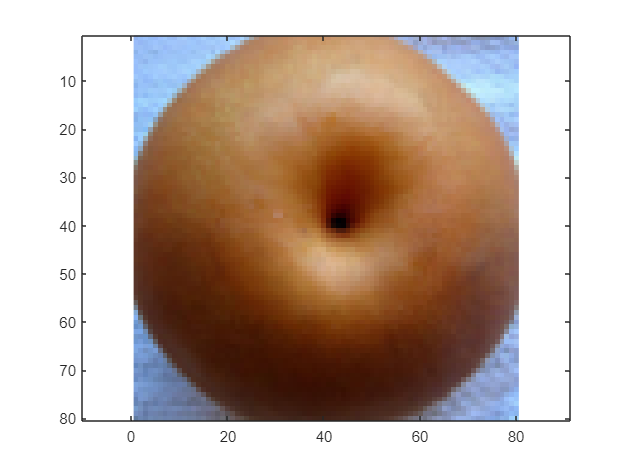

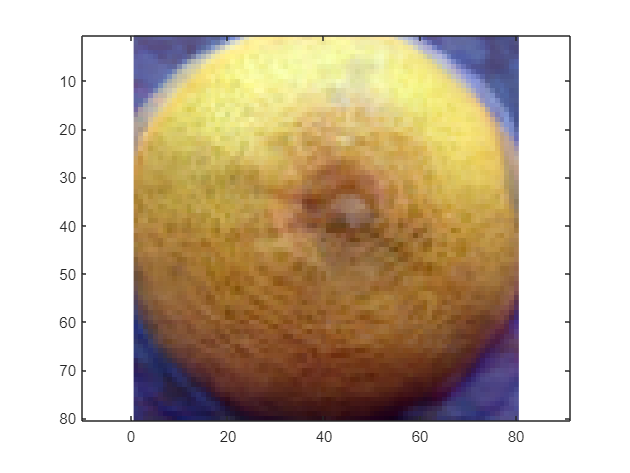

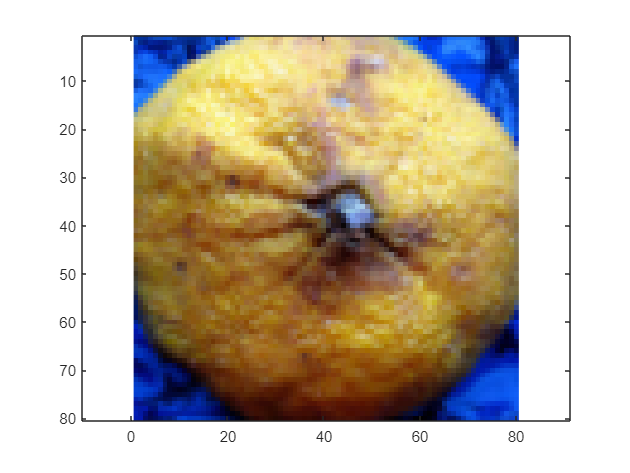

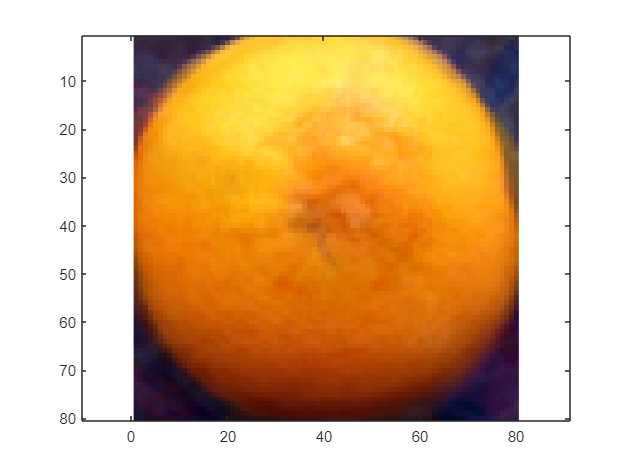

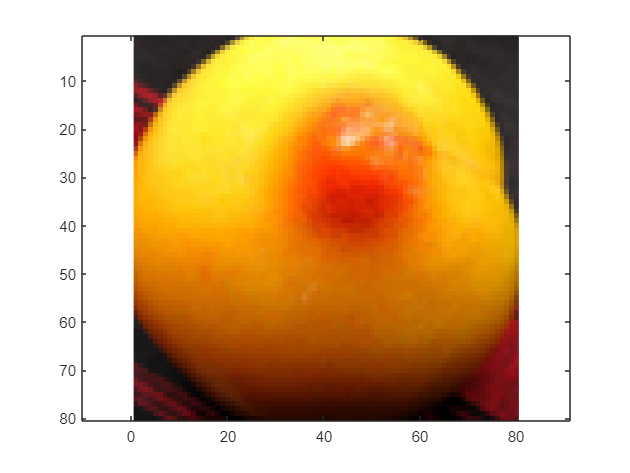

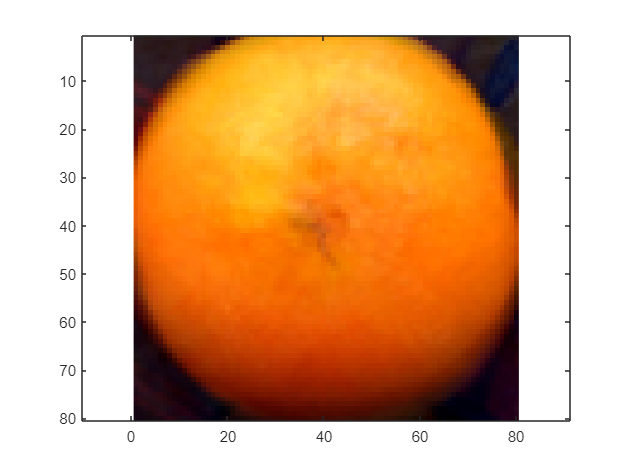

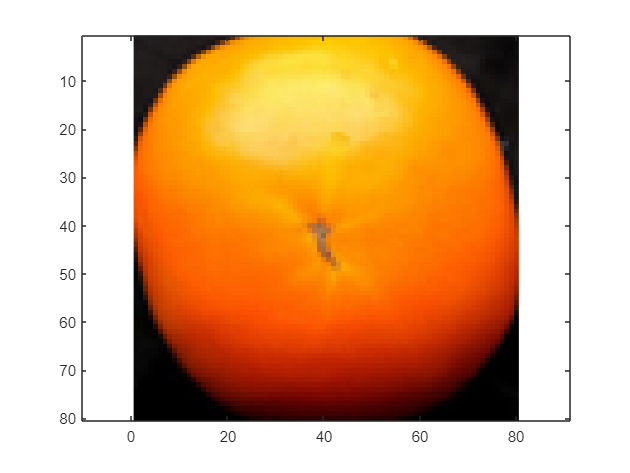


%Creating representative images using the theorem mentioned in the report
finalAns=zeros(19200, 16);
for k=1:16
    finalAns(:, k)=((EigenVec(:,1))'*(imageResize(:,k)-mean)).*(EigenVec(:,1))+((EigenVec(:,2))'*(imageResize(:,k)-mean)).*(EigenVec(:,2))+((EigenVec(:,3))'*(imageResize(:,k)-mean)).*(EigenVec(:,3))+((EigenVec(:,4))'*(imageResize(:,k)-mean)).*(EigenVec(:,4))+mean;
end
finalAns=uint8(finalAns);
for l=1:16
    %PLotting the representative images
    reshaped=reshape((finalAns(:,l)), [80,80,3]);
    figure, imagesc(reshaped);
    axis equal;
    imageResize1=uint8(imageResize);
    figure, imagesc(reshape(imageResize1(:,l), [80, 80, 3]));
    axis equal;
end

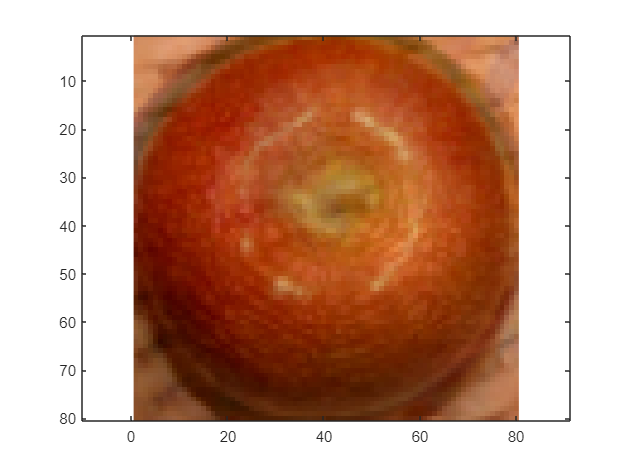

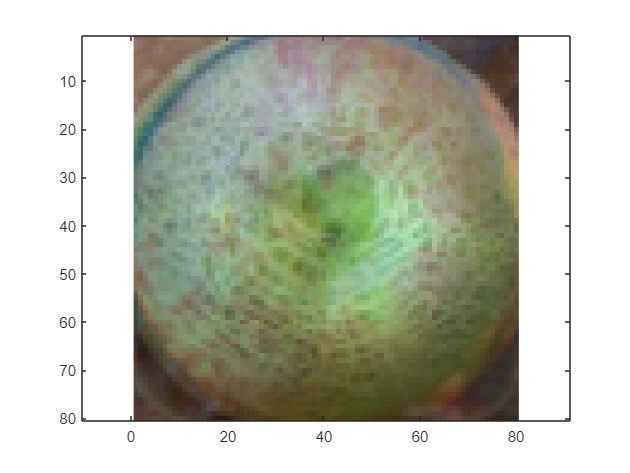

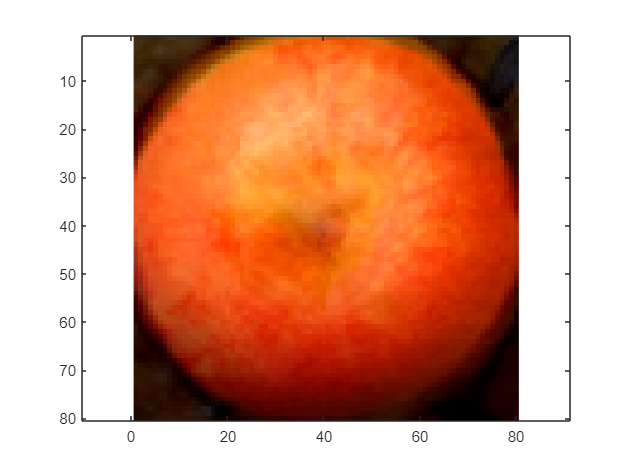


%Creating the random images using alternate values of imageResize
new=zeros(19200, 16);
for k=1:3
    new(:, k)=((EigenVec(:,1))'*(imageResize(:,1*k)-mean)).*(EigenVec(:,1))+((EigenVec(:,2))'*(imageResize(:,3*k)-mean)).*(EigenVec(:,2))+((EigenVec(:,3))'*(imageResize(:,4*k)-mean)).*(EigenVec(:,3))+((EigenVec(:,4))'*(imageResize(:,5*k)-mean)).*(EigenVec(:,4))+mean;
end
new=uint8(new);
%Plotting the random images
for k=1:3
    figure, imagesc(reshape((new(:,k)), [80, 80, 3]));
    axis equal;
end